# Machine Learning: Programming Exercise 3

## Multi-class Classification and Neural Networks

In this exercise, you will implement one-vs-all logistic regression and neural networks to recognize hand-written digits.

### Files needed for this exercise

- `ex3.mlx` - MATLAB Live Script that steps you through the exercise

- `ex3data1.mat` - Training set of hand-written digits

- `ex3weights.mat` - Initial weights for the neural network exercise

- `submit.m `- Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `*lrCostFunction.m` - Logistic regression cost function

- `*oneVsAll.m` - Train a one-vs-all multi-class classifier

- `*predictOneVsAll.m` - Predict using a one-vs-all multi-class classifier

- `*predict.m `- Neural network prediction function

****indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex3' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir


.                  ex3.mlx            ex3data1.mat       lib                predict.m          submit.m           
..                 ex3_companion.mat  ex3weights.mat     lrCostFunction.m   predictOneVsAll.m  
displayData.m      ex3_companion.mlx  fmincg.m           oneVsAll.m         sigmoid.m          



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Multi-class Classification

For this exercise, you will use logistic regression and neural networks to recognize handwritten digits (from 0 to 9). Automated handwritten digit recognition is widely used today - from recognizing zip codes (postal codes) on mail envelopes to recognizing amounts written on bank checks. This exercise will show you how the methods you've learned can be used for this classication task. In the first part of the exercise, you will extend your previous implemention of logistic regression and apply it to one-vs-all classification.

### 1.1 Dataset

You are given a data set in `ex3data1.mat` that contains 5000 training examples of handwritten digits*. The .mat format means that that the data has been saved in a native MATLAB matrix format, instead of a text (ASCII) format like a csv-file. These matrices can be read directly into your program by using the load command. After loading, matrices of the correct dimensions and values will appear in your program's memory. The matrix will already be named, so you do not need to assign names to them. 

**This is a subset of the MNIST *[*handwritten digit dataset*](http://yann.lecun.com/exdb/mnist/))

Run the code below to load the data.

% Load saved matrices from file
load('ex3data1.mat');
% The matrices X and y will now be in your MATLAB environment

    There are 5000 training examples in `ex3data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


    The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

## 1.2 Visualizing the data

You will begin by visualizing a subset of the training set. The code below randomly selects selects 100 rows from `X` and passes those rows to the `displayData` function. This function maps each row to a 20 pixel by 20 pixel grayscale image and displays the images together. We have provided the `displayData` function, and you are encouraged to examine the code to see how it works. After you run this step, you should see an image like Figure 1.

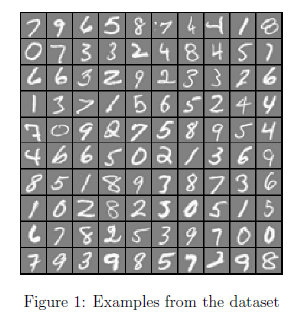                        

m = size(X, 1);
% Randomly select 100 data points to display
rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);

displayData(sel);

### 1.3 Vectorizing logistic regression

You will be using multiple one-vs-all logistic regression models to build a multi-class classifier. Since there are 10 classes, you will need to train 10 separate logistic regression classifiers. To make this training efficient, it is important to ensure that your code is well vectorized. In this section, you will implement a vectorized version of logistic regression that does not employ any `for` loops. You can use your code in the last exercise as a starting point for this exercise.

#### 1.3.1 Vectorizing the cost function

We will begin by writing a vectorized version of the cost function. Recall that in (unregularized) logistic regression, the cost function is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1-y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


To compute each element in the summation, we have to compute $h_{\theta}(x^{(i)})$ for every example $i$, where $h_{\theta}(x^{(i)}) = g(\theta^T x^{(i)})$ and $g(z) =\frac{1}{1+e^{-z}}$ is the sigmoid function. It turns out that we can compute this quickly for all our examples by using matrix multiplication. Let us define $X$ and $\theta$ as


$$X\theta \;=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T \theta \;-\\
-{\left(x^{\left(2\right)} \right)}^T \theta \;-\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T \theta \;-
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\;\theta^T \left(x^{\left(1\right)} \right)-\\
-{\;\theta }^T \left(x^{\left(2\right)} \right)\;-\\
\vdots \\
-{\;\theta }^T \left(x^{\left(m\right)} \right)-
\end{array}\right\rbrack \;$$


In the last equality, we used the fact that $a^T b= b^T a$ if $a$ and $b$ are vectors. This allows us to compute the products $\theta^T x^{(i)}$ for all our examples $i$ in one line of code.

    Your job is to write the unregularized cost function in the file `lrCostFunction.m `Your implementation should use the strategy we presented above to calculate $\theta^T x^{(i)}$. You should also use a vectorized approach for the rest of the cost function. A fully vectorized version of `lrCostFunction.m` should not contain any loops. (Hint: You might want to use the element-wise multiplication operation (`.*`) and the sum operation `sum` when writing this function)

#### 1.3.2 Vectorizing the gradient

Recall that the gradient of the (unregularized) logistic regression cost is a vector where the $j$th element is defined as 


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}
$$


To vectorize this operation over the dataset, we start by writing out all the partial derivatives explicitly for all $\theta_j$,

$\left[ \begin{array}{c} 
\frac{\partial J(\theta)}{\partial \theta_0} \\
\frac{\partial J(\theta)}{\partial \theta_1} \\
\frac{\partial J(\theta)}{\partial \theta_2} \\
\vdots \\
\frac{\partial J(\theta)}{\partial \theta_n}   
 \end{array} \right]
 = \frac{1}{m}
\left[ \begin{array}{c} 
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_0^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_1^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_2^{(i)} \\
\vdots \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_n^{(i)}
\end{array}\right] =\frac{1}{m} \sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x^{(i)} =
\frac{1}{m}X^T {\left( h_\theta(x)-y\right)}
$   (1)

where


$$h_{\theta \;} \left(x\right)-y=\left\lbrack \begin{array}{c}
h_{\theta \;} \left(x^{\left(1\right)} \right)-y^{\left(1\right)} \\
h_{\theta \;} \left(x^{\left(2\right)} \right)-y^{\left(2\right)} \\
\vdots \\
h_{\theta \;} \left(x^{\left(m\right)} \right)-y^{\left(m\right)} 
\end{array}\right\rbrack$$


    Note that $x^{(i)}$ is a vector, while $(h_\theta(x^{(i)})-y^{(i)})$ is a scalar (single number). To understand the last step of the derivation, let $\beta_i = (h_\theta(x^{(i)})-y^{(i)})$ and observe that:


$$\sum_i \beta_i x^{\left(i\right)} =\left\lbrack \begin{array}{cccc}
| & | & \; & |\\
x^{\left(1\right)}  & x^{\left(2\right)}  & \dots  & x^{\left(m\right)} \\
| & | & \; & |
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\beta_1 \\
\beta_2 \\
\vdots \\
\beta_m 
\end{array}\right\rbrack =X^T \beta ,$$


    The expression above allows us to compute all the partial derivatives without any loops. If you are comfortable with linear algebra, we encourage you to work through the matrix multiplications above to convince yourself that the vectorized version does the same computations. You should now implement Equation (1) to compute the correct vectorized gradient. Once you are done, complete the function `lrCostFunction.m` by implementing the gradient.

**Debugging Tip: **Vectorizing code can sometimes be tricky. One common strategy for debugging is to print out the sizes of the matrices you are working with using the size function. For example, given a data matrix $X$ of size 100 x 20 (100 examples, 20 features) and $\theta$, a vector with dimensions 20 x 1, you can observe that $X\theta$ is a valid multiplication operation, while $\theta X$ is not. Furthermore, if you have a non-vectorized version of your code, you can compare the output of your vectorized code and non-vectorized code to make sure that they produce the same outputs.

#### 1.3.3 Vectorizing regularized logistic regression

After you have implemented vectorization for logistic regression, you will now add regularization to the cost function. Recall that for regularized logistic regression, the cost function is defined as


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2}$$


Note that you should not be regularizing $\theta_0$ which is used for the bias term. Correspondingly, the partial derivative of regularized logistic regression cost for $\theta_j$ is defined as


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,
$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1$$


Now modify your code in `lrCostFunction` to account for regularization. Once again, you should not put any loops into your code. When you are finished, run the code below to test your vectorized implementation and compare to expected outputs:

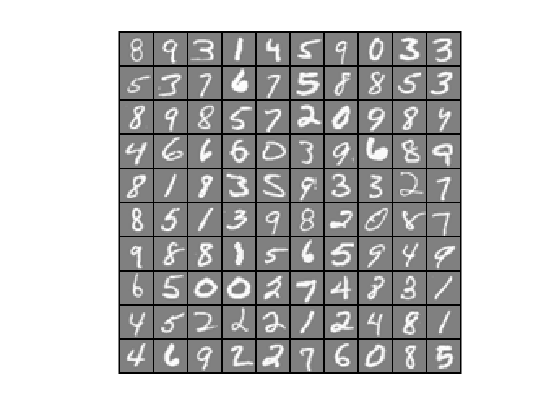

theta_t = [-2; -1; 1; 2];
X_t = [ones(5,1) reshape(1:15,5,3)/10];
y_t = ([1;0;1;0;1] >= 0.5);
lambda_t = 3;
[J, grad] = lrCostFunction(theta_t, X_t, y_t, lambda_t);


fprintf('Cost: %f | Expected cost: 2.534819\n',J);
fprintf('Gradients:\n'); fprintf('%f\n',grad);
fprintf('Expected gradients:\n 0.146561\n -0.548558\n 0.724722\n 1.398003');

**MATLAB Tip:** When implementing the vectorization for regularized logistic regression, you might often want to only sum and update certain elements of $\theta$. In MATLAB, you can index into the matrices to access and update only certain elements. For example, `A(:,3:5)= B(:, 1:3)` will replace columns 3 to 5 of `A` with the columns 1 to 3 from `B`. One special keyword you can use in indexing is the `end` keyword in indexing. This allows us to select columns (or rows) until the end of the matrix. For example, `A(:, 2:end)` will only return elements from the 2nd to last column of `A`. Thus, you could use this together with the `sum` and `.^` operations to compute the sum of only the elements you are interested in (e.g. `sum(z(2:end).^2))`. In the starter code,` lrCostFunction.m`, we have also provided hints on yet another possible method computing the regularized gradient.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 One-vs-all classication

In this part of the exercise, you will implement one-vs-all classification by training multiple regularized logistic regression classifiers, one for each of the $K$ classes in our dataset (Figure 1). In the handwritten digits dataset, $K = 10$, but your code should work for any value of $K$. 

    You should now complete the code in `oneVsAll.m` to train one classifier for each class. In particular, your code should return all the classifier parameters in a matrix $\Theta \in \mathbb{R}^{K\times(N+1)}$, where each row of $\Theta$ corresponds to the learned logistic regression parameters for one class. You can do this with a `for` loop from 1 to `K`, training each classifier independently.

Note that the `y` argument to this function is a vector of labels from 1 to 10, where we have mapped the digit '0' to the label 10 (to avoid confusions with indexing). When training the classifier for class $k \in \{1,\ldots,K\},$ you will want a $m$-dimensional vector of labels $y,$ where $y_j\in \{0,\;1\}$ indicates whether the $j$-th training instance belongs to class $k\; (y_j = 1)$, or if it belongs to a different class $(y_j = 0).$ You may find logical arrays helpful for this task.

**MATLAB Tip**: Logical arrays in MATLAB are arrays which contain binary (0 or 1) elements. In MATLAB, evaluating the expression `a == b` for a vector `a` (of size $m\times1$) and scalar `b` will return a vector of the same size as `a` with ones at positions where the elements of `a` are equal to `b` and zeroes where they are different. To see how this works for yourself, run the following code:

a = 1:10; % Create a and b
b = 3;
disp(a == b) % You should try different values of b here

Furthermore, you will be using `fmincg` for this exercise (instead of `fminunc`). `fmincg` works similarly to `fminunc`, but is more more efficient for dealing with a large number of parameters. After you have correctly completed the code for `oneVsAll.m`, run the code below to use your `oneVsAll` function to train a multi-class classifier.

num_labels = 10; % 10 labels, from 1 to 10 
lambda = 0.1;

J = 0.7348

[all_theta] = oneVsAll(X, y, num_labels, lambda);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.4.1 One-vs-all prediction

After training your one-vs-all classifier, you can now use it to predict the digit contained in a given image. For each input, you should compute the 'probability' that it belongs to each class using the trained logistic regression classifiers. Your one-vs-all prediction function will pick the class for which the corresponding logistic regression classifier outputs the highest probability and return the class label $(1, 2,..., \text{ or } K)$ as the prediction for the input example.

    You should now complete the code in `predictOneVsAll.m` to use the one-vs-all classifier to make predictions. Once you are done, run the code below to call your `predictOneVsAll` function using the learned value of $\Theta$. You should see that the training set  accuracy is about 94.9% (i.e., it classifies 94.9% of the examples in the training set correctly).

pred = predictOneVsAll(all_theta, X);

Cost: 2.534819 | Expected cost: 2.534819


fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

Gradients:
0.146561
-0.548558
0.724722
1.398003


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Neural Networks

In the previous part of this exercise, you implemented multi-class logistic regression to recognize handwritten digits. However, logistic regression cannot form more complex hypotheses as it is only a linear classier. (You could add more features such as polynomial features to logistic regression, but that can be very expensive to train*.) *In this part of the exercise, you will implement a neural network to recognize handwritten digits using the same training set as before. The neural network will be able to represent complex models that form non-linear hypotheses. 

    For this week, you will be using parameters from a neural network that we have already trained. Your goal is to implement the feedforward propagation algorithm to use our weights for prediction. In next week's exercise, you will write the backpropagation algorithm for learning the neural network parameters.

### 2.1 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (excluding the extra bias unit which always outputs +1). As before, the training data will be loaded into the variables `X` and `y`.

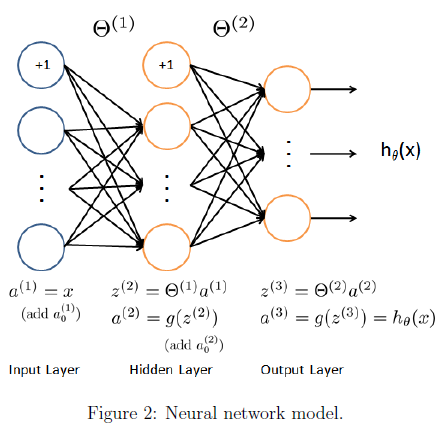

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex3weights.mat` and are loaded into `Theta1` and `Theta2 `by running the code below. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

load('ex3data1.mat');

Expected gradients:
 0.146561
 -0.548558
 0.724722
 1.398003

m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

% Load saved matrices from file
load('ex3weights.mat'); 
% Theta1 has size 25 x 401
% Theta2 has size 10 x 26

### 2.2 Feedforward propagation and prediction

Now you will implement feedforward propagation for the neural network. You will need to complete the code in `predict.m` to return the neural network's prediction. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and returns the associated predictions. Similar to the one-vs-all classication strategy, the prediction from the neural network will be the label that has the largest output $(h_\theta(x))_k$.

**Implementation Note: **The matrix `X` contains the examples in rows. When you complete the code in `predict.m`, you will need to add the column of 1's to the matrix. The matrices `Theta1` and `Theta2` contain the parameters for each unit in rows. Specically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. In MATLAB, when you compute $z^{(2)} = \Theta^{(1)}a^{(1)}$, be sure that you index (and if necessary, transpose) `X` correctly so that you get $a^{(1)}$ as a column vector.

Once you are done, run the code below to call your predict function using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the accuracy is about 97.5%.

pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

   0   0   1   0   0   0   0   0   0   0



The code below will displaying images from the training set one at a time, while the console prints out the predicted label for the displayed image. Rerun to repeat with another image.

%  Randomly permute examples
rp = randi(m);
% Predict
pred = predict(Theta1, Theta2, X(rp,:));

J = 0.6931

J = 0.2802

Iteration     1 | Cost: 2.802128e-01


J = 0.0945

Iteration     2 | Cost: 9.454389e-02


J = 1.2015

J = 0.0859

J = 0.0570

Iteration     3 | Cost: 5.704641e-02


J = 0.0837

J = 0.0468

Iteration     4 | Cost: 4.688190e-02


J = 0.0373

Iteration     5 | Cost: 3.759021e-02


J = 0.0830

J = 0.0349

Iteration     6 | Cost: 3.522008e-02


J = 0.0319

Iteration     7 | Cost: 3.234531e-02


J = 0.0359

J = 0.0310

Iteration     8 | Cost: 3.145034e-02


J = 0.0296

Iteration     9 | Cost: 3.008919e-02


J = 0.0340

J = 0.0295

Iteration    10 | Cost: 2.994639e-02


J = 0.0292

J = 0.0287

J = 0.0274

J = 0.0263

Iteration    11 | Cost: 2.678528e-02


J = 0.0823

J = 0.0262

J = 0.0262

Iteration    12 | Cost: 2.660323e-02


J = 0.0258

J = 0.0252

J = 0.0244

Iteration    13 | Cost: 2.493301e-02


J = 0.0356

J = 0.0242

Iteration    14 | Cost: 2.475211e-02


J = 0.0239

J = 0.0233

J = 0.0225

Iteration    15 | Cost: 2.318421e-02


J = 0.0270

J = 0.0221

Iteration    16 | Cost: 2.287050e-02


J = 0.0215

J = 0.0207

Iteration    17 | Cost: 2.160258e-02


J = 0.0211

J = 0.0203

Iteration    18 | Cost: 2.120371e-02


J = 0.0197

Iteration    19 | Cost: 2.064125e-02


J = 0.0211

J = 0.0196

Iteration    20 | Cost: 2.055695e-02


J = 0.0195

Iteration    21 | Cost: 2.045466e-02


J = 0.0194

J = 0.0194

Iteration    22 | Cost: 2.029177e-02


J = 0.0191

Iteration    23 | Cost: 2.005296e-02


J = 0.0190

J = 0.0190

Iteration    24 | Cost: 1.995949e-02


J = 0.0189

Iteration    25 | Cost: 1.982849e-02


J = 0.0188

Iteration    26 | Cost: 1.975129e-02


J = 0.0186

J = 0.0183

J = 0.0178

Iteration    27 | Cost: 1.897815e-02


J = 0.0210

J = 0.0177

Iteration    28 | Cost: 1.887065e-02


J = 0.0174

Iteration    29 | Cost: 1.869107e-02


J = 0.0174

J = 0.0174

Iteration    30 | Cost: 1.863223e-02


J = 0.0173

J = 0.0171

Iteration    31 | Cost: 1.837394e-02


J = 0.0169

Iteration    32 | Cost: 1.816951e-02


J = 0.0166

J = 0.0165

Iteration    33 | Cost: 1.781689e-02


J = 0.0176

J = 0.0164

Iteration    34 | Cost: 1.774665e-02


J = 0.0163

Iteration    35 | Cost: 1.767439e-02


J = 0.0162

Iteration    36 | Cost: 1.758469e-02


J = 0.0163

J = 0.0162

Iteration    37 | Cost: 1.756847e-02


J = 0.0162

J = 0.0162

Iteration    38 | Cost: 1.753343e-02


J = 0.0161

J = 0.0159

J = 0.0158

Iteration    39 | Cost: 1.727929e-02


J = 0.0154

Iteration    40 | Cost: 1.701831e-02


J = 0.0148

J = 0.0140

Iteration    41 | Cost: 1.621660e-02


J = 0.0127

Iteration    42 | Cost: 1.536149e-02


J = 0.0119

J = 0.0119

Iteration    43 | Cost: 1.488704e-02


J = 0.0109

Iteration    44 | Cost: 1.449609e-02


J = 0.0105

J = 0.0105

Iteration    45 | Cost: 1.427745e-02


J = 0.0104

J = 0.0103

Iteration    46 | Cost: 1.418857e-02


J = 0.0101

J = 0.0097

Iteration    47 | Cost: 1.386899e-02


J = 0.0104

J = 0.0096

Iteration    48 | Cost: 1.381336e-02


J = 0.0096

Iteration    49 | Cost: 1.375577e-02


J = 0.0095

Iteration    50 | Cost: 1.369480e-02


J = 0.6931

J = 0.3449

Iteration     1 | Cost: 3.448901e-01


J = 0.3149

Iteration     2 | Cost: 3.150694e-01


J = 0.1842

Iteration     3 | Cost: 1.846843e-01


J = NaN

J = NaN

J = NaN

J = 0.1840

J = 0.1692

Iteration     4 | Cost: 1.699017e-01


J = 0.1522

Iteration     5 | Cost: 1.529566e-01


J = 0.1310

Iteration     6 | Cost: 1.317377e-01


J = 0.1164

Iteration     7 | Cost: 1.171533e-01


J = 0.1130

J = 0.1067

Iteration     8 | Cost: 1.074286e-01


J = 0.0946

Iteration     9 | Cost: 9.531806e-02


J = 0.1080

J = 0.0924

Iteration    10 | Cost: 9.301912e-02


J = 0.0880

J = 0.0836

Iteration    11 | Cost: 8.418356e-02


J = 0.0975

J = 0.0813

Iteration    12 | Cost: 8.186322e-02


J = 0.0781

J = 0.0768

Iteration    13 | Cost: 7.743126e-02


J = 0.0872

J = 0.0759

Iteration    14 | Cost: 7.645181e-02


J = 0.0741

J = 0.0716

Iteration    15 | Cost: 7.209877e-02


J = 0.1478

J = 0.0716

J = 0.0714

Iteration    16 | Cost: 7.195896e-02


J = 0.0712

J = 0.0708

J = 0.0705

Iteration    17 | Cost: 7.106302e-02


J = 0.0723

J = 0.0703

Iteration    18 | Cost: 7.081516e-02


J = 0.0699

J = 0.0693

Iteration    19 | Cost: 6.984782e-02


J = 0.0685

Iteration    20 | Cost: 6.908892e-02


J = 0.0676

Iteration    21 | Cost: 6.818820e-02


J = 0.0698

J = 0.0675

Iteration    22 | Cost: 6.804182e-02


J = 0.0673

Iteration    23 | Cost: 6.788125e-02


J = 0.0673

J = 0.0672

Iteration    24 | Cost: 6.779397e-02


J = 0.0671

Iteration    25 | Cost: 6.767277e-02


J = 0.0670

Iteration    26 | Cost: 6.760372e-02


J = 0.0669

J = 0.0668

Iteration    27 | Cost: 6.740638e-02


J = 0.0669

J = 0.0667

Iteration    28 | Cost: 6.731728e-02


J = 0.0666

J = 0.0664

Iteration    29 | Cost: 6.698888e-02


J = 0.0670

J = 0.0664

Iteration    30 | Cost: 6.692984e-02


J = 0.0662

J = 0.0660

J = 0.0657

Iteration    31 | Cost: 6.630404e-02


J = 0.0659

J = 0.0655

Iteration    32 | Cost: 6.606809e-02


J = 0.0650

J = 0.0644

J = 0.0640

Iteration    33 | Cost: 6.466816e-02


J = 0.0658

J = 0.0636

Iteration    34 | Cost: 6.426962e-02


J = 0.0628

J = 0.0619

Iteration    35 | Cost: 6.267791e-02


J = 0.0700

J = 0.0617

Iteration    36 | Cost: 6.251576e-02


J = 0.0614

J = 0.0612

Iteration    37 | Cost: 6.202834e-02


J = 0.0616

J = 0.0610

Iteration    38 | Cost: 6.188521e-02


J = 0.0607

J = 0.0601

J = 0.0590

Iteration    39 | Cost: 6.013896e-02


J = 0.0580

Iteration    40 | Cost: 5.937078e-02


J = 0.0589

J = 0.0575

Iteration    41 | Cost: 5.888593e-02


J = 0.0575

J = 0.0573

Iteration    42 | Cost: 5.862828e-02


J = 0.0576

J = 0.0572

Iteration    43 | Cost: 5.854428e-02


J = 0.0571

Iteration    44 | Cost: 5.847598e-02


J = 0.0570

Iteration    45 | Cost: 5.840091e-02


J = 0.0569

J = 0.0567

Iteration    46 | Cost: 5.812347e-02


J = 0.0569

J = 0.0566

Iteration    47 | Cost: 5.803255e-02


J = 0.0564

J = 0.0562

Iteration    48 | Cost: 5.773508e-02


J = 0.0563

J = 0.0561

Iteration    49 | Cost: 5.763069e-02


J = 0.0559

J = 0.0557

Iteration    50 | Cost: 5.725245e-02


J = 0.6931

J = 0.3457

Iteration     1 | Cost: 3.456557e-01


J = 0.4051

J = 0.2179

Iteration     2 | Cost: 2.179164e-01


J = 0.1783

Iteration     3 | Cost: 1.784174e-01


J = NaN

J = 0.2428

J = 0.1676

Iteration     4 | Cost: 1.678808e-01


J = 0.1487

J = 0.1425

Iteration     5 | Cost: 1.427129e-01


J = 0.1149

Iteration     6 | Cost: 1.150393e-01


J = 0.1232

J = 0.1062

Iteration     7 | Cost: 1.063718e-01


J = 0.0969

Iteration     8 | Cost: 9.707803e-02


J = 0.1281

J = 0.0950

Iteration     9 | Cost: 9.518367e-02


J = 0.0922

J = 0.0902

Iteration    10 | Cost: 9.035733e-02


J = 0.1059

J = 0.0891

Iteration    11 | Cost: 8.928846e-02


J = 0.0873

J = 0.0851

Iteration    12 | Cost: 8.531186e-02


J = 0.0837

J = 0.0831

Iteration    13 | Cost: 8.333526e-02


J = 0.0802

Iteration    14 | Cost: 8.052683e-02


J = 0.0794

J = 0.0790

Iteration    15 | Cost: 7.932857e-02


J = 0.0771

J = 0.0764

Iteration    16 | Cost: 7.672637e-02


J = 0.0749

Iteration    17 | Cost: 7.530942e-02


J = 0.0876

J = 0.0746

Iteration    18 | Cost: 7.500108e-02


J = 0.0740

Iteration    19 | Cost: 7.445295e-02


J = 0.0735

Iteration    20 | Cost: 7.391453e-02


J = 0.0731

Iteration    21 | Cost: 7.349869e-02


J = 0.0727

Iteration    22 | Cost: 7.307295e-02


J = 0.0733

J = 0.0726

Iteration    23 | Cost: 7.296937e-02


J = 0.0724

J = 0.0722

Iteration    24 | Cost: 7.262398e-02


J = 0.0717

J = 0.0709

Iteration    25 | Cost: 7.129794e-02


J = 0.0759

J = 0.0707

Iteration    26 | Cost: 7.118480e-02


J = 0.0705

J = 0.0704

Iteration    27 | Cost: 7.089717e-02


J = 0.0699

J = 0.0691

Iteration    28 | Cost: 6.963444e-02


J = 0.0957

J = 0.0692

J = 0.0691

Iteration    29 | Cost: 6.959800e-02


J = 0.0690

J = 0.0689

J = 0.0687

Iteration    30 | Cost: 6.916222e-02


J = 0.0684

Iteration    31 | Cost: 6.893779e-02


J = 0.0728

J = 0.0684

J = 0.0684

Iteration    32 | Cost: 6.891920e-02


J = 0.0684

J = 0.0683

J = 0.0682

Iteration    33 | Cost: 6.872561e-02


J = 0.0680

Iteration    34 | Cost: 6.853821e-02


J = 0.0684

J = 0.0680

Iteration    35 | Cost: 6.849984e-02


J = 0.0679

J = 0.0677

J = 0.0673

J = 0.0669

Iteration    36 | Cost: 6.754698e-02


J = 0.0673

J = 0.0664

Iteration    37 | Cost: 6.715053e-02


J = 0.0657

J = 0.0650

Iteration    38 | Cost: 6.581156e-02


J = 0.0760

J = 0.0649

Iteration    39 | Cost: 6.572406e-02


J = 0.0647

Iteration    40 | Cost: 6.555445e-02


J = 0.0645

J = 0.0643

Iteration    41 | Cost: 6.515063e-02


J = 0.0637

Iteration    42 | Cost: 6.464354e-02


J = 0.0639

J = 0.0636

Iteration    43 | Cost: 6.449652e-02


J = 0.0634

Iteration    44 | Cost: 6.435632e-02


J = 0.0634

J = 0.0633

Iteration    45 | Cost: 6.428798e-02


J = 0.0632

Iteration    46 | Cost: 6.419460e-02


J = 0.0633

J = 0.0632

Iteration    47 | Cost: 6.416972e-02


J = 0.0631

J = 0.0631

Iteration    48 | Cost: 6.405955e-02


J = 0.0632

J = 0.0631

Iteration    49 | Cost: 6.403990e-02


J = 0.0630

Iteration    50 | Cost: 6.401887e-02


J = 0.6931

J = 0.3205

Iteration     1 | Cost: 3.205301e-01


J = 0.3040

Iteration     2 | Cost: 3.040759e-01


J = 0.1646

Iteration     3 | Cost: 1.649080e-01


J = NaN

J = NaN

J = 0.2031

J = 0.1431

Iteration     4 | Cost: 1.438784e-01


J = 0.0935

Iteration     5 | Cost: 9.416994e-02


J = 0.3720

J = 0.0898

Iteration     6 | Cost: 9.044270e-02


J = 0.0823

J = 0.0744

Iteration     7 | Cost: 7.499076e-02


J = 0.1138

J = 0.0714

Iteration     8 | Cost: 7.202465e-02


J = 0.0670

J = 0.0626

Iteration     9 | Cost: 6.313221e-02


J = 0.0907

J = 0.0611

Iteration    10 | Cost: 6.168143e-02


J = 0.0588

J = 0.0571

Iteration    11 | Cost: 5.762801e-02


J = 0.0622

J = 0.0558

Iteration    12 | Cost: 5.638036e-02


J = 0.0546

Iteration    13 | Cost: 5.517793e-02


J = 0.0535

Iteration    14 | Cost: 5.405985e-02


J = 0.0527

Iteration    15 | Cost: 5.332997e-02


J = 0.0511

Iteration    16 | Cost: 5.177817e-02


J = 0.0496

Iteration    17 | Cost: 5.019780e-02


J = 0.0604

J = 0.0494

Iteration    18 | Cost: 5.009061e-02


J = 0.0492

J = 0.0489

J = 0.0487

Iteration    19 | Cost: 4.933097e-02


J = 0.0492

J = 0.0484

Iteration    20 | Cost: 4.906466e-02


J = 0.0479

J = 0.0472

Iteration    21 | Cost: 4.795495e-02


J = 0.0549

J = 0.0471

Iteration    22 | Cost: 4.787525e-02


J = 0.0470

J = 0.0467

J = 0.0466

Iteration    23 | Cost: 4.736363e-02


J = 0.0463

J = 0.0462

Iteration    24 | Cost: 4.703862e-02


J = 0.0457

J = 0.0451

Iteration    25 | Cost: 4.594095e-02


J = 0.0509

J = 0.0449

Iteration    26 | Cost: 4.581040e-02


J = 0.0447

J = 0.0442

J = 0.0434

Iteration    27 | Cost: 4.439892e-02


J = 0.0468

J = 0.0432

Iteration    28 | Cost: 4.419341e-02


J = 0.0428

J = 0.0424

Iteration    29 | Cost: 4.354888e-02


J = 0.0415

Iteration    30 | Cost: 4.267134e-02


J = 0.0474

J = 0.0414

Iteration    31 | Cost: 4.260402e-02


J = 0.0413

J = 0.0412

Iteration    32 | Cost: 4.239221e-02


J = 0.0412

J = 0.0411

Iteration    33 | Cost: 4.229365e-02


J = 0.0409

Iteration    34 | Cost: 4.216166e-02


J = 0.0408

J = 0.0407

Iteration    35 | Cost: 4.195637e-02


J = 0.0410

J = 0.0406

Iteration    36 | Cost: 4.190375e-02


J = 0.0405

J = 0.0403

J = 0.0397

J = 0.0386

Iteration    37 | Cost: 4.031431e-02


J = 0.0465

J = 0.0383

Iteration    38 | Cost: 4.011239e-02


J = 0.0379

J = 0.0372

J = 0.0362

Iteration    39 | Cost: 3.861574e-02


J = 0.0431

J = 0.0360

Iteration    40 | Cost: 3.840651e-02


J = 0.0354

J = 0.0346

J = 0.0338

Iteration    41 | Cost: 3.692758e-02


J = 0.0421

J = 0.0336

Iteration    42 | Cost: 3.672099e-02


J = 0.0333

Iteration    43 | Cost: 3.644744e-02


J = 0.0338

J = 0.0332

Iteration    44 | Cost: 3.641048e-02


J = 0.0332

J = 0.0331

Iteration    45 | Cost: 3.625610e-02


J = 0.0331

J = 0.0330

Iteration    46 | Cost: 3.620340e-02


J = 0.0329

Iteration    47 | Cost: 3.613431e-02


J = 0.0329

Iteration    48 | Cost: 3.609230e-02


J = 0.0329

J = 0.0329

Iteration    49 | Cost: 3.606380e-02


J = 0.0328

J = 0.0328

Iteration    50 | Cost: 3.599201e-02


J = 0.6931

J = 0.3314

Iteration     1 | Cost: 3.314410e-01


J = 0.3994

J = 0.2217

Iteration     2 | Cost: 2.217377e-01


J = 0.3207

J = 0.1929

Iteration     3 | Cost: 1.929205e-01


J = 0.1567

Iteration     4 | Cost: 1.568866e-01


J = 0.1820

J = 0.1316

Iteration     5 | Cost: 1.318005e-01


J = 0.1180

J = 0.1146

Iteration     6 | Cost: 1.147878e-01


J = 0.1635

J = 0.1122

Iteration     7 | Cost: 1.124131e-01


J = 0.1082

Iteration     8 | Cost: 1.083564e-01


J = 0.1085

J = 0.1067

Iteration     9 | Cost: 1.069107e-01


J = 0.1044

J = 0.1021

Iteration    10 | Cost: 1.022962e-01


J = 0.1181

J = 0.1015

Iteration    11 | Cost: 1.017049e-01


J = 0.1002

J = 0.0985

Iteration    12 | Cost: 9.879326e-02


J = 0.0974

J = 0.0971

Iteration    13 | Cost: 9.731696e-02


J = 0.0945

J = 0.0918

Iteration    14 | Cost: 9.216899e-02


J = 0.0926

J = 0.0900

Iteration    15 | Cost: 9.032623e-02


J = 0.0866

J = 0.0835

Iteration    16 | Cost: 8.409627e-02


J = 0.0848

J = 0.0807

Iteration    17 | Cost: 8.140204e-02


J = 0.0778

Iteration    18 | Cost: 7.863906e-02


J = 0.0936

J = 0.0775

Iteration    19 | Cost: 7.835122e-02


J = 0.0769

J = 0.0762

Iteration    20 | Cost: 7.711350e-02


J = 0.0768

J = 0.0758

Iteration    21 | Cost: 7.671192e-02


J = 0.0751

J = 0.0744

Iteration    22 | Cost: 7.538515e-02


J = 0.0782

J = 0.0742

Iteration    23 | Cost: 7.517315e-02


J = 0.0738

J = 0.0731

J = 0.0725

Iteration    24 | Cost: 7.352966e-02


J = 0.0726

J = 0.0717

Iteration    25 | Cost: 7.269690e-02


J = 0.0706

Iteration    26 | Cost: 7.167827e-02


J = 0.0746

J = 0.0705

Iteration    27 | Cost: 7.156798e-02


J = 0.0703

J = 0.0700

Iteration    28 | Cost: 7.107344e-02


J = 0.0695

Iteration    29 | Cost: 7.057249e-02


J = 0.0737

J = 0.0695

Iteration    30 | Cost: 7.054742e-02


J = 0.0694

Iteration    31 | Cost: 7.051131e-02


J = 0.0694

J = 0.0693

J = 0.0692

Iteration    32 | Cost: 7.027145e-02


J = 0.0692

J = 0.0691

Iteration    33 | Cost: 7.015020e-02


J = 0.0688

J = 0.0685

Iteration    34 | Cost: 6.963282e-02


J = 0.0681

Iteration    35 | Cost: 6.921892e-02


J = 0.0675

Iteration    36 | Cost: 6.867102e-02


J = 0.0713

J = 0.0675

Iteration    37 | Cost: 6.864035e-02


J = 0.0674

J = 0.0673

J = 0.0672

Iteration    38 | Cost: 6.838629e-02


J = 0.0677

J = 0.0671

Iteration    39 | Cost: 6.832040e-02


J = 0.0670

J = 0.0668

Iteration    40 | Cost: 6.803653e-02


J = 0.0665

Iteration    41 | Cost: 6.775374e-02


J = 0.0662

J = 0.0660

Iteration    42 | Cost: 6.726246e-02


J = 0.0655

Iteration    43 | Cost: 6.682707e-02


J = 0.0645

J = 0.0631

Iteration    44 | Cost: 6.472359e-02


J = 0.0637

J = 0.0625

Iteration    45 | Cost: 6.415015e-02


J = 0.0616

Iteration    46 | Cost: 6.345012e-02


J = 0.0610

Iteration    47 | Cost: 6.292337e-02


J = 0.0602

Iteration    48 | Cost: 6.240582e-02


J = 0.0597

Iteration    49 | Cost: 6.199857e-02


J = 0.0593

J = 0.0592

Iteration    50 | Cost: 6.174866e-02


J = 0.6931

J = 0.3355

Iteration     1 | Cost: 3.354875e-01


J = 0.2188

Iteration     2 | Cost: 2.188639e-01


J = 0.0974

Iteration     3 | Cost: 9.772130e-02


J = NaN

J = NaN

J = NaN

J = 0.1106

J = 0.0840

Iteration     4 | Cost: 8.460314e-02


J = 0.0595

Iteration     5 | Cost: 5.991024e-02


J = 0.0956

J = 0.0528

Iteration     6 | Cost: 5.318810e-02


J = 0.0448

Iteration     7 | Cost: 4.521935e-02


J = 0.0408

Iteration     8 | Cost: 4.117442e-02


J = 0.0554

J = 0.0394

Iteration     9 | Cost: 3.978801e-02


J = 0.0383

Iteration    10 | Cost: 3.874084e-02


J = 0.0377

Iteration    11 | Cost: 3.814846e-02


J = 0.0759

J = 0.0380

J = 0.0377

Iteration    12 | Cost: 3.812015e-02


J = 0.0377

J = 0.0376

J = 0.0375

Iteration    13 | Cost: 3.791387e-02


J = 0.0371

J = 0.0368

Iteration    14 | Cost: 3.720946e-02


J = 0.0358

J = 0.0353

Iteration    15 | Cost: 3.578365e-02


J = 0.0344

J = 0.0343

Iteration    16 | Cost: 3.474696e-02


J = 0.0335

Iteration    17 | Cost: 3.395842e-02


J = 0.0335

J = 0.0330

Iteration    18 | Cost: 3.351052e-02


J = 0.0330

J = 0.0328

Iteration    19 | Cost: 3.326145e-02


J = 0.0328

J = 0.0326

Iteration    20 | Cost: 3.314033e-02


J = 0.0324

J = 0.0320

J = 0.0312

Iteration    21 | Cost: 3.180976e-02


J = 0.0317

J = 0.0307

Iteration    22 | Cost: 3.138624e-02


J = 0.0300

J = 0.0293

Iteration    23 | Cost: 3.012590e-02


J = 0.0283

Iteration    24 | Cost: 2.930241e-02


J = 0.0283

J = 0.0276

Iteration    25 | Cost: 2.893186e-02


J = 0.0269

J = 0.0266

Iteration    26 | Cost: 2.802475e-02


J = 0.0251

Iteration    27 | Cost: 2.666012e-02


J = 0.0306

J = 0.0250

Iteration    28 | Cost: 2.654574e-02


J = 0.0248

J = 0.0245

J = 0.0242

Iteration    29 | Cost: 2.573053e-02


J = 0.0244

J = 0.0239

Iteration    30 | Cost: 2.537199e-02


J = 0.0237

Iteration    31 | Cost: 2.517240e-02


J = 0.0265

J = 0.0236

Iteration    32 | Cost: 2.513433e-02


J = 0.0236

J = 0.0235

Iteration    33 | Cost: 2.503069e-02


J = 0.0234

Iteration    34 | Cost: 2.494552e-02


J = 0.0241

J = 0.0234

Iteration    35 | Cost: 2.493218e-02


J = 0.0234

J = 0.0234

J = 0.0233

Iteration    36 | Cost: 2.480206e-02


J = 0.0231

J = 0.0227

Iteration    37 | Cost: 2.433127e-02


J = 0.0222

Iteration    38 | Cost: 2.390570e-02


J = 0.0216

Iteration    39 | Cost: 2.342356e-02


J = 0.0309

J = 0.0217

J = 0.0216

Iteration    40 | Cost: 2.341140e-02


J = 0.0216

J = 0.0216

J = 0.0215

Iteration    41 | Cost: 2.329351e-02


J = 0.0212

J = 0.0209

Iteration    42 | Cost: 2.283085e-02


J = 0.0210

J = 0.0207

Iteration    43 | Cost: 2.269664e-02


J = 0.0207

J = 0.0206

Iteration    44 | Cost: 2.260818e-02


J = 0.0205

J = 0.0204

Iteration    45 | Cost: 2.241249e-02


J = 0.0208

J = 0.0203

Iteration    46 | Cost: 2.236848e-02


J = 0.0202

J = 0.0201

J = 0.0199

Iteration    47 | Cost: 2.205982e-02


J = 0.0226

J = 0.0198

Iteration    48 | Cost: 2.202830e-02


J = 0.0198

J = 0.0197

J = 0.0195

Iteration    49 | Cost: 2.177326e-02


J = 0.0203

J = 0.0194

Iteration    50 | Cost: 2.172999e-02


J = 0.6931

J = 0.3143

Iteration     1 | Cost: 3.142799e-01


J = 0.1938

Iteration     2 | Cost: 1.938915e-01


J = 0.2318

J = 0.0984

Iteration     3 | Cost: 9.858322e-02


J = NaN

J = 0.1338

J = 0.0861

Iteration     4 | Cost: 8.666461e-02


J = 0.0848

J = 0.0648

Iteration     5 | Cost: 6.518233e-02


J = 0.1418

J = 0.0612

Iteration     6 | Cost: 6.163782e-02


J = 0.0585

Iteration     7 | Cost: 5.886007e-02


J = 0.0604

J = 0.0573

Iteration     8 | Cost: 5.773973e-02


J = 0.0555

J = 0.0530

Iteration     9 | Cost: 5.334455e-02


J = 0.0500

Iteration    10 | Cost: 5.036396e-02


J = 0.0713

J = 0.0496

Iteration    11 | Cost: 4.994868e-02


J = 0.0493

Iteration    12 | Cost: 4.964157e-02


J = 0.0492

J = 0.0491

Iteration    13 | Cost: 4.945483e-02


J = 0.0488

Iteration    14 | Cost: 4.920530e-02


J = 0.0485

J = 0.0484

Iteration    15 | Cost: 4.880147e-02


J = 0.0477

J = 0.0472

Iteration    16 | Cost: 4.766125e-02


J = 0.0463

Iteration    17 | Cost: 4.683578e-02


J = 0.0451

Iteration    18 | Cost: 4.573370e-02


J = 0.0444

Iteration    19 | Cost: 4.507942e-02


J = 0.0672

J = 0.0444

J = 0.0443

Iteration    20 | Cost: 4.501869e-02


J = 0.0442

J = 0.0440

J = 0.0436

Iteration    21 | Cost: 4.433528e-02


J = 0.0427

J = 0.0420

Iteration    22 | Cost: 4.271154e-02


J = 0.0533

J = 0.0418

Iteration    23 | Cost: 4.251498e-02


J = 0.0415

J = 0.0412

Iteration    24 | Cost: 4.191880e-02


J = 0.0423

J = 0.0411

Iteration    25 | Cost: 4.178635e-02


J = 0.0408

J = 0.0407

Iteration    26 | Cost: 4.147292e-02


J = 0.0414

J = 0.0407

Iteration    27 | Cost: 4.139877e-02


J = 0.0405

J = 0.0404

Iteration    28 | Cost: 4.119548e-02


J = 0.0401

J = 0.0397

Iteration    29 | Cost: 4.051792e-02


J = 0.0412

J = 0.0395

Iteration    30 | Cost: 4.039230e-02


J = 0.0393

J = 0.0389

Iteration    31 | Cost: 3.980250e-02


J = 0.0387

J = 0.0386

Iteration    32 | Cost: 3.956674e-02


J = 0.0382

J = 0.0377

Iteration    33 | Cost: 3.884197e-02


J = 0.0368

Iteration    34 | Cost: 3.804694e-02


J = 0.0364

Iteration    35 | Cost: 3.768877e-02


J = 0.0400

J = 0.0363

Iteration    36 | Cost: 3.759177e-02


J = 0.0362

Iteration    37 | Cost: 3.745400e-02


J = 0.0360

J = 0.0359

Iteration    38 | Cost: 3.719879e-02


J = 0.0372

J = 0.0359

Iteration    39 | Cost: 3.716378e-02


J = 0.0358

J = 0.0357

Iteration    40 | Cost: 3.701026e-02


J = 0.0363

J = 0.0357

Iteration    41 | Cost: 3.699550e-02


J = 0.0357

J = 0.0356

Iteration    42 | Cost: 3.693462e-02


J = 0.0356

Iteration    43 | Cost: 3.690108e-02


J = 0.0355

J = 0.0354

Iteration    44 | Cost: 3.680227e-02


J = 0.0353

Iteration    45 | Cost: 3.670963e-02


J = 0.0352

J = 0.0350

Iteration    46 | Cost: 3.641835e-02


J = 0.0360

J = 0.0350

Iteration    47 | Cost: 3.636866e-02


J = 0.0349

J = 0.0348

Iteration    48 | Cost: 3.621258e-02


J = 0.0353

J = 0.0347

Iteration    49 | Cost: 3.618559e-02


J = 0.0347

J = 0.0346

J = 0.0344

Iteration    50 | Cost: 3.592514e-02


J = 0.6931

J = 0.3693

Iteration     1 | Cost: 3.693354e-01


J = 0.4871

J = 0.2565

Iteration     2 | Cost: 2.565067e-01


J = 0.2369

Iteration     3 | Cost: 2.370476e-01


J = NaN

J = NaN

J = 0.3332

J = 0.2339

Iteration     4 | Cost: 2.341589e-01


J = 0.2211

J = 0.2102

Iteration     5 | Cost: 2.103654e-01


J = 0.1780

Iteration     6 | Cost: 1.781526e-01


J = 0.1733

J = 0.1659

Iteration     7 | Cost: 1.659830e-01


J = 0.1522

Iteration     8 | Cost: 1.523508e-01


J = 0.2288

J = 0.1505

Iteration     9 | Cost: 1.506519e-01


J = 0.1478

J = 0.1436

J = 0.1399

Iteration    10 | Cost: 1.400809e-01


J = 0.2037

J = 0.1382

Iteration    11 | Cost: 1.383318e-01


J = 0.1351

J = 0.1300

J = 0.1227

Iteration    12 | Cost: 1.229135e-01


J = 0.1979

J = 0.1203

Iteration    13 | Cost: 1.205599e-01


J = 0.1166

J = 0.1121

Iteration    14 | Cost: 1.123879e-01


J = 0.1245

J = 0.1108

Iteration    15 | Cost: 1.110733e-01


J = 0.1083

J = 0.1070

Iteration    16 | Cost: 1.073286e-01


J = 0.1407

J = 0.1066

Iteration    17 | Cost: 1.068798e-01


J = 0.1060

J = 0.1056

Iteration    18 | Cost: 1.058981e-01


J = 0.1086

J = 0.1054

Iteration    19 | Cost: 1.056835e-01


J = 0.1050

J = 0.1043

J = 0.1027

J = 0.1017

Iteration    20 | Cost: 1.019768e-01


J = 0.1110

J = 0.1007

Iteration    21 | Cost: 1.010370e-01


J = 0.0993

J = 0.0979

Iteration    22 | Cost: 9.828022e-02


J = 0.1232

J = 0.0978

Iteration    23 | Cost: 9.812436e-02


J = 0.0976

Iteration    24 | Cost: 9.792314e-02


J = 0.0971

J = 0.0965

Iteration    25 | Cost: 9.689705e-02


J = 0.1221

J = 0.0966

J = 0.0965

Iteration    26 | Cost: 9.686948e-02


J = 0.0965

J = 0.0964

J = 0.0961

J = 0.0959

Iteration    27 | Cost: 9.630516e-02


J = 0.0957

J = 0.0956

Iteration    28 | Cost: 9.595524e-02


J = 0.0949

J = 0.0940

Iteration    29 | Cost: 9.439663e-02


J = 0.0938

J = 0.0934

Iteration    30 | Cost: 9.385266e-02


J = 0.0930

Iteration    31 | Cost: 9.343079e-02


J = 0.0922

Iteration    32 | Cost: 9.268394e-02


J = 0.0915

Iteration    33 | Cost: 9.194399e-02


J = 0.0907

Iteration    34 | Cost: 9.122537e-02


J = 0.0905

J = 0.0904

Iteration    35 | Cost: 9.091222e-02


J = 0.0904

J = 0.0902

Iteration    36 | Cost: 9.075900e-02


J = 0.0900

Iteration    37 | Cost: 9.055132e-02


J = 0.0897

J = 0.0893

Iteration    38 | Cost: 8.988152e-02


J = 0.0892

J = 0.0891

Iteration    39 | Cost: 8.962559e-02


J = 0.0890

J = 0.0889

Iteration    40 | Cost: 8.948804e-02


J = 0.0888

Iteration    41 | Cost: 8.933891e-02


J = 0.0886

Iteration    42 | Cost: 8.918858e-02


J = 0.0894

J = 0.0886

Iteration    43 | Cost: 8.917012e-02


J = 0.0885

J = 0.0885

J = 0.0883

J = 0.0880

Iteration    44 | Cost: 8.862973e-02


J = 0.0886

J = 0.0878

Iteration    45 | Cost: 8.848802e-02


J = 0.0875

J = 0.0871

J = 0.0864

Iteration    46 | Cost: 8.721201e-02


J = 0.0929

J = 0.0862

Iteration    47 | Cost: 8.702008e-02


J = 0.0858

J = 0.0854

Iteration    48 | Cost: 8.624419e-02


J = 0.0858

J = 0.0852

Iteration    49 | Cost: 8.605396e-02


J = 0.0848

J = 0.0846

Iteration    50 | Cost: 8.555349e-02


J = 0.6931

J = 0.3369

Iteration     1 | Cost: 3.369306e-01


J = 0.6807

J = 0.2513

Iteration     2 | Cost: 2.513191e-01


J = 0.2358

Iteration     3 | Cost: 2.358271e-01


J = NaN

J = NaN

J = 0.5555

J = 0.2418

J = 0.2352

Iteration     4 | Cost: 2.352523e-01


J = 0.2336

J = 0.2305

J = 0.2219

J = 0.2010

J = 0.1866

Iteration     5 | Cost: 1.867055e-01


J = 0.1526

Iteration     6 | Cost: 1.526791e-01


J = 0.3628

J = 0.1503

J = 0.1488

Iteration     7 | Cost: 1.488460e-01


J = 0.1425

J = 0.1384

Iteration     8 | Cost: 1.385401e-01


J = 0.1752

J = 0.1362

Iteration     9 | Cost: 1.363013e-01


J = 0.1325

J = 0.1275

Iteration    10 | Cost: 1.276495e-01


J = 0.1348

J = 0.1257

Iteration    11 | Cost: 1.258539e-01


J = 0.1224

J = 0.1192

Iteration    12 | Cost: 1.193549e-01


J = 0.1138

Iteration    13 | Cost: 1.139919e-01


J = 0.1068

Iteration    14 | Cost: 1.070966e-01


J = 0.1049

J = 0.1034

Iteration    15 | Cost: 1.037065e-01


J = 0.0989

Iteration    16 | Cost: 9.936582e-02


J = 0.1152

J = 0.0984

Iteration    17 | Cost: 9.883916e-02


J = 0.0975

J = 0.0969

Iteration    18 | Cost: 9.734415e-02


J = 0.1018

J = 0.0966

Iteration    19 | Cost: 9.705827e-02


J = 0.0961

J = 0.0953

Iteration    20 | Cost: 9.578377e-02


J = 0.1025

J = 0.0952

Iteration    21 | Cost: 9.569713e-02


J = 0.0951

J = 0.0948

J = 0.0944

Iteration    22 | Cost: 9.483495e-02


J = 0.0942

J = 0.0939

Iteration    23 | Cost: 9.439928e-02


J = 0.0931

J = 0.0919

J = 0.0909

Iteration    24 | Cost: 9.143805e-02


J = 0.0985

J = 0.0903

Iteration    25 | Cost: 9.082974e-02


J = 0.0894

Iteration    26 | Cost: 8.992841e-02


J = 0.0917

J = 0.0893

Iteration    27 | Cost: 8.982376e-02


J = 0.0891

J = 0.0889

Iteration    28 | Cost: 8.939125e-02


J = 0.0886

Iteration    29 | Cost: 8.917813e-02


J = 0.0905

J = 0.0886

Iteration    30 | Cost: 8.913997e-02


J = 0.0885

J = 0.0884

J = 0.0882

Iteration    31 | Cost: 8.878267e-02


J = 0.0878

Iteration    32 | Cost: 8.832439e-02


J = 0.0878

J = 0.0876

Iteration    33 | Cost: 8.816152e-02


J = 0.0873

J = 0.0870

Iteration    34 | Cost: 8.757947e-02


J = 0.0872

J = 0.0868

Iteration    35 | Cost: 8.739025e-02


J = 0.0865

J = 0.0864

Iteration    36 | Cost: 8.699304e-02


J = 0.0884

J = 0.0863

Iteration    37 | Cost: 8.693589e-02


J = 0.0862

J = 0.0860

J = 0.0856

Iteration    38 | Cost: 8.623919e-02


J = 0.0881

J = 0.0855

Iteration    39 | Cost: 8.616867e-02


J = 0.0854

J = 0.0852

Iteration    40 | Cost: 8.587694e-02


J = 0.0850

Iteration    41 | Cost: 8.572464e-02


J = 0.0863

J = 0.0850

Iteration    42 | Cost: 8.569679e-02


J = 0.0850

J = 0.0849

J = 0.0847

Iteration    43 | Cost: 8.539772e-02


J = 0.0843

Iteration    44 | Cost: 8.505203e-02


J = 0.0846

J = 0.0843

Iteration    45 | Cost: 8.497517e-02


J = 0.0842

Iteration    46 | Cost: 8.489747e-02


J = 0.0840

J = 0.0838

J = 0.0834

Iteration    47 | Cost: 8.425403e-02


J = 0.0822

J = 0.0803

Iteration    48 | Cost: 8.141555e-02


J = 0.0827

J = 0.0797

Iteration    49 | Cost: 8.083507e-02


J = 0.0788

Iteration    50 | Cost: 8.007308e-02


J = 0.6931

J = 0.3478

Iteration     1 | Cost: 3.478011e-01


J = 0.2074

Iteration     2 | Cost: 2.074559e-01


J = 0.1105

Iteration     3 | Cost: 1.108108e-01


J = NaN

J = NaN

J = NaN

J = 0.1330

J = 0.0968

Iteration     4 | Cost: 9.723535e-02


J = 0.0667

J = 0.0480

Iteration     5 | Cost: 4.845901e-02


J = 2.9720

J = 0.0470

J = 0.0453

Iteration     6 | Cost: 4.571820e-02


J = 0.0404

J = 0.0336

Iteration     7 | Cost: 3.405605e-02


J = 0.1361

J = 0.0331

Iteration     8 | Cost: 3.350113e-02


J = 0.0316

J = 0.0295

J = 0.0279

Iteration     9 | Cost: 2.829574e-02


J = 0.0396

J = 0.0263

Iteration    10 | Cost: 2.671193e-02


J = 0.0240

J = 0.0225

Iteration    11 | Cost: 2.288809e-02


J = 0.1256

J = 0.0224

J = 0.0223

Iteration    12 | Cost: 2.267282e-02


J = 0.0218

J = 0.0212

J = 0.0200

Iteration    13 | Cost: 2.048262e-02


J = 0.0245

J = 0.0195

Iteration    14 | Cost: 2.001572e-02


J = 0.0187

J = 0.0176

Iteration    15 | Cost: 1.815609e-02


J = 0.0218

J = 0.0174

Iteration    16 | Cost: 1.791330e-02


J = 0.0169

J = 0.0167

Iteration    17 | Cost: 1.723808e-02


J = 0.0174

J = 0.0164

Iteration    18 | Cost: 1.702208e-02


J = 0.0160

J = 0.0157

Iteration    19 | Cost: 1.633115e-02


J = 0.0152

Iteration    20 | Cost: 1.586407e-02


J = 0.0154

J = 0.0148

Iteration    21 | Cost: 1.557474e-02


J = 0.0146

Iteration    22 | Cost: 1.528102e-02


J = 0.0143

Iteration    23 | Cost: 1.500042e-02


J = 0.0154

J = 0.0142

Iteration    24 | Cost: 1.495532e-02


J = 0.0141

J = 0.0140

J = 0.0139

Iteration    25 | Cost: 1.464703e-02


J = 0.0139

J = 0.0137

Iteration    26 | Cost: 1.450265e-02


J = 0.0134

J = 0.0131

Iteration    27 | Cost: 1.399742e-02


J = 0.0125

Iteration    28 | Cost: 1.345917e-02


J = 0.0122

Iteration    29 | Cost: 1.321219e-02


J = 0.0269

J = 0.0122

J = 0.0122

Iteration    30 | Cost: 1.320100e-02


J = 0.0122

J = 0.0121

J = 0.0120

J = 0.0119

Iteration    31 | Cost: 1.294498e-02


J = 0.0116

Iteration    32 | Cost: 1.260010e-02


J = 0.0131

J = 0.0115

Iteration    33 | Cost: 1.256812e-02


J = 0.0115

J = 0.0114

Iteration    34 | Cost: 1.243740e-02


J = 0.0113

Iteration    35 | Cost: 1.236272e-02


J = 0.0112

J = 0.0112

Iteration    36 | Cost: 1.230297e-02


J = 0.0111

Iteration    37 | Cost: 1.223894e-02


J = 0.0111

Iteration    38 | Cost: 1.217598e-02


J = 0.0111

J = 0.0110

Iteration    39 | Cost: 1.214853e-02


J = 0.0110

J = 0.0110

Iteration    40 | Cost: 1.208406e-02


J = 0.0108

J = 0.0105

J = 0.0101

Iteration    41 | Cost: 1.149927e-02


J = 0.0090

Iteration    42 | Cost: 1.073544e-02


J = 0.0084

Iteration    43 | Cost: 1.018228e-02


J = 0.0193

J = 0.0084

J = 0.0084

Iteration    44 | Cost: 1.015541e-02


J = 0.0083

J = 0.0082

Iteration    45 | Cost: 1.004798e-02


J = 0.0081

Iteration    46 | Cost: 9.995635e-03


J = 0.0081

J = 0.0081

Iteration    47 | Cost: 9.971678e-03


J = 0.0080

Iteration    48 | Cost: 9.938707e-03


J = 0.0080

J = 0.0080

Iteration    49 | Cost: 9.888462e-03


J = 0.0079

Iteration    50 | Cost: 9.828149e-03



Training Set Accuracy: 94.960000


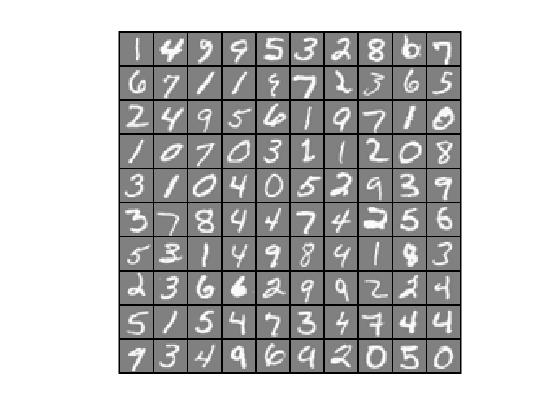


Training Set Accuracy: 97.520000



Neural Network Prediction: 7 (digit 7)


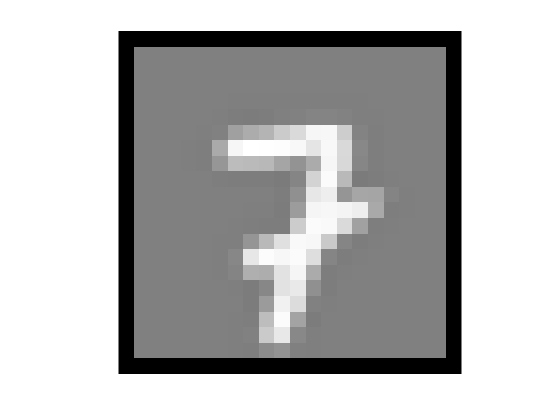

fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred, mod(pred, 10));
% Display 
displayData(X(rp, :));   

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## Submission and Grading

After completing this assignment, be sure to use the submit function to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

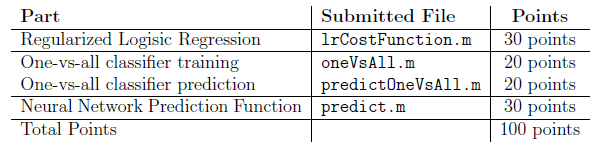

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.